# Session 5/6

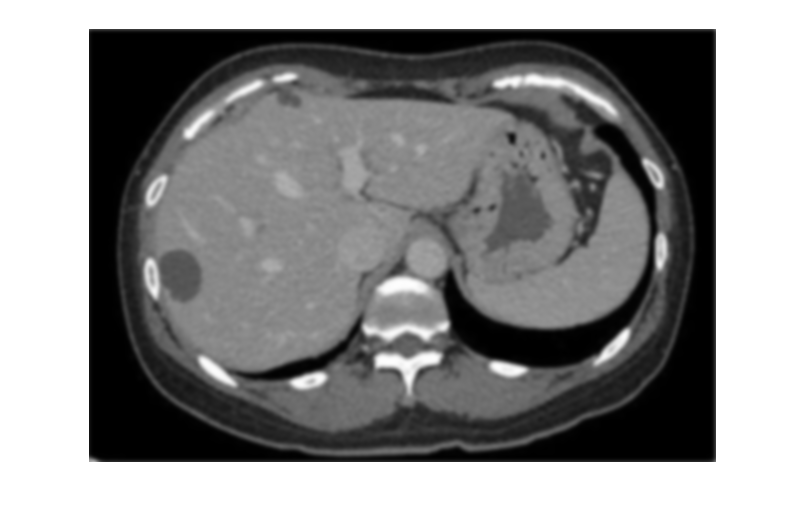

% adding Gaussian filter blurs original image
imCyst=imgaussfilt(imread("liver_cyste.jpg"),2);
imshow(imCyst)

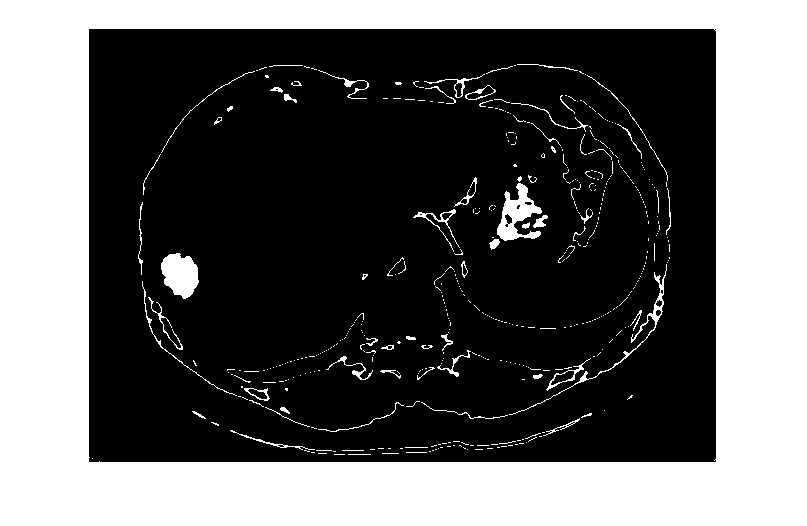


% only keep between these values
binCyst=((imCyst >= 80) & (imCyst < 90));
imshow(binCyst)

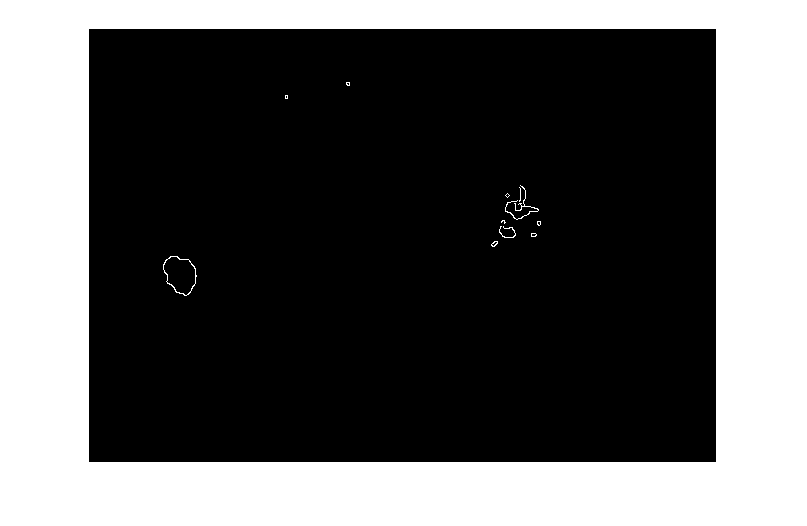


edgcyst=(edge(imerode(binCyst,strel('square',5)),'canny'));
imshow(edgcyst);

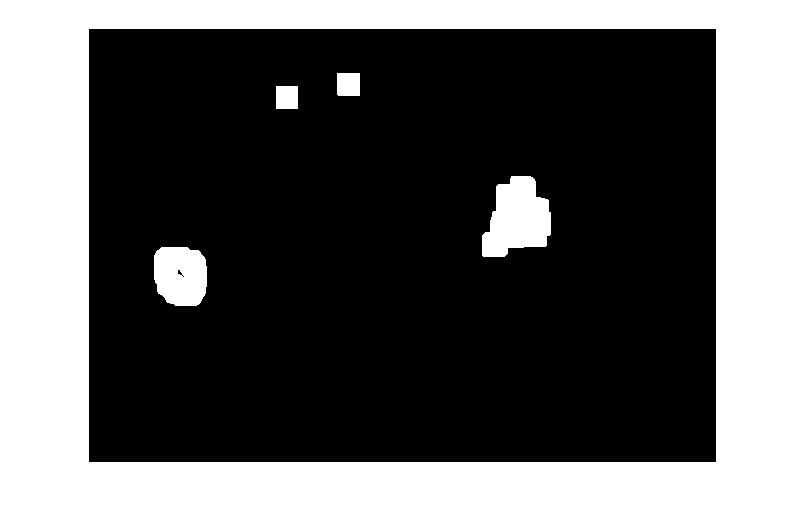

whitcyst=(imdilate(edgcyst,strel('square',20)));
imshow(whitcyst)

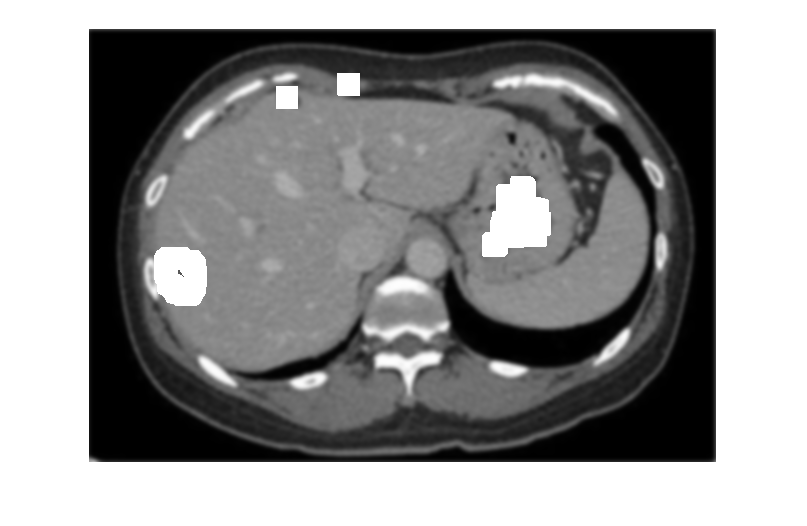

imshow(imCyst+uint8(whitcyst)*(255))